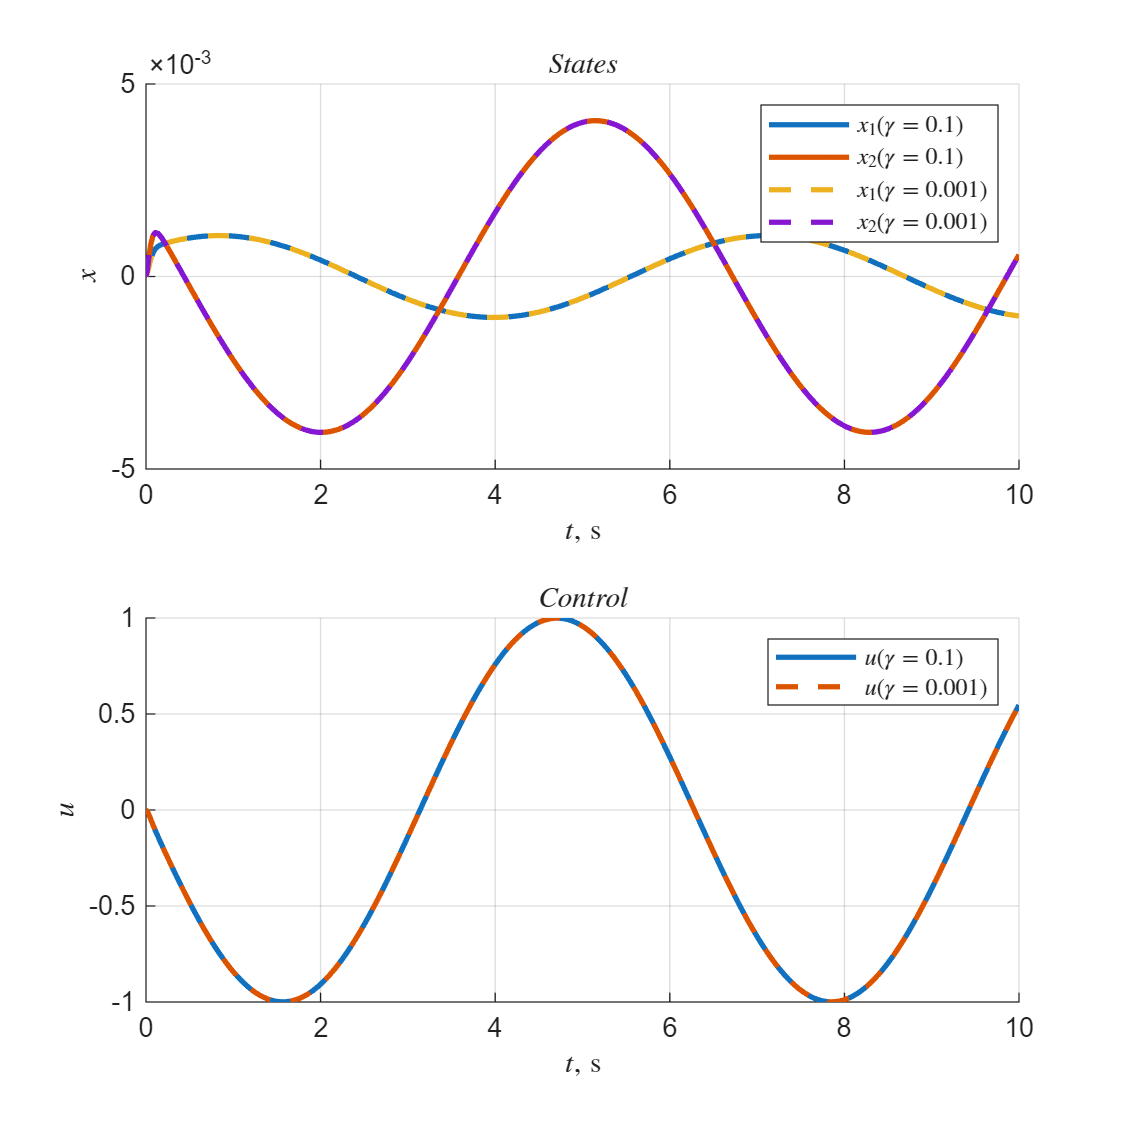

A = [3 1; 1 1];
b = [1; 2];
d = b;
kf1 = 0.2;
kf0 = 0.01;
gamma1 = 0.1;
gamma2 = 0.001;
K = [434.225220821837 -178.650599773935];
Q = eye(2);
AM = A - b*K;
P = lyap(AM.', Q);

simtime = 10;
gamma = gamma1;
out = sim("lab11.slx", simtime);
x1 = out.x.Data;
u1 = out.u.Data;
t1 = out.x.Time;
gamma = gamma2;
out = sim("lab11.slx", simtime);
x2 = out.x.Data;
u2 = out.u.Data;
t2 = out.x.Time;

f = figure;
f.Position = [100 100 1200 1200];

subplot(2,1,1);
hold on;
plot(t1, x1, LineWidth=2);
plot(t2, x2, LineStyle="--", LineWidth=2);
hold off;

legend({ ...
    sprintf('$x_1(\\gamma=%g)$', gamma1), ...
    sprintf('$x_2(\\gamma=%g)$', gamma1), ...
    sprintf('$x_1(\\gamma=%g)$', gamma2), ...
    sprintf('$x_2(\\gamma=%g)$', gamma2)}, ...
    Interpreter="latex");

grid on;
title("$States$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$x$", Interpreter="latex");

subplot(2,1,2);
hold on;
plot(t1, u1, LineWidth=2);
plot(t2, u2, LineStyle="--", LineWidth=2);
hold off;

legend({ ...
    sprintf('$u(\\gamma=%g)$', gamma1), ...
    sprintf('$u(\\gamma=%g)$', gamma2)}, ...
    Interpreter="latex");

grid on;
title("$Control$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$u$", Interpreter="latex");